## Code Goal: Assess driver of rapid rise in water level

%Example 1. BLM16 on July 16, 2021. Rapid water level rise, see time lapse
%imagery and water level data. 

%Past hypothesis has been that it was air pressure drops that did this.
%This alone is unsupoorted, there were larger drops in air pressure that
%did nothing at this site. 

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses'
cd Groundwater\RapidWaterLevelRise\data\input\

load('BLM16_AirPresCor.mat')
load('BLM93C_AirPresCor.mat')
load('Bflat30min.mat')

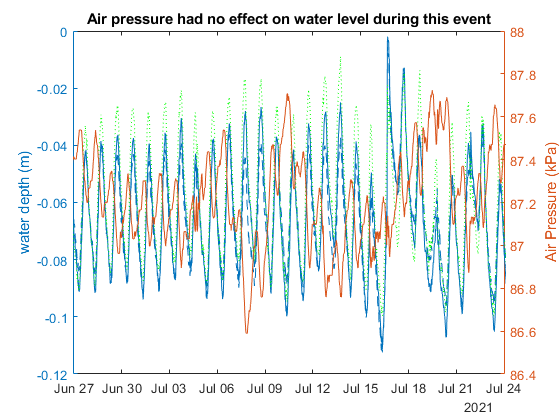

%Plot data

figure

yyaxis left

plot(BLM16.Date_Time_MDT, -BLM16.EquivalentHead_HaliteSaturated_BelowSurf_m)
hold on 
plot(BLM16.Date_Time_MDT, -BLM16.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)
plot(BLM93C.Date_Time_MDT, -BLM93C.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, 'color', 'green', 'DisplayName','BLM93C')
ylabel('water depth (m)')

yyaxis right
plot(Bflat30min.Date_Time_MDT, Bflat30min.Pressure_kPa)
ylabel('Air Pressure (kPa)')
xlim(BLM16.Date_Time_MDT([700,2000]))
title('Air pressure had no effect on water level during this event')

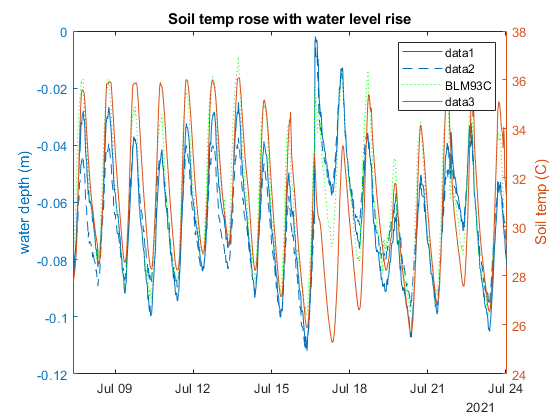

figure

yyaxis left

plot(BLM16.Date_Time_MDT, -BLM16.EquivalentHead_HaliteSaturated_BelowSurf_m)
hold on 
plot(BLM16.Date_Time_MDT, -BLM16.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)
plot(BLM93C.Date_Time_MDT, -BLM93C.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, 'color', 'green', 'DisplayName','BLM93C')

ylabel('water depth (m)')

yyaxis right
plot(Bflat30min.Date_Time_MDT, Bflat30min.SoilTemp_C)
ylabel('Soil temp (C)')
legend

xlim(BLM16.Date_Time_MDT([1200,2000]))
title('Soil temp rose with water level rise')

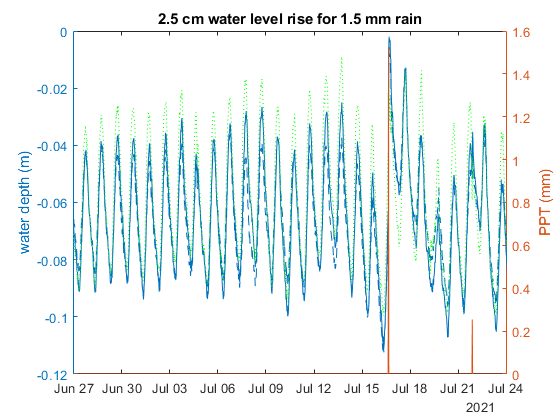

figure

yyaxis left

plot(BLM16.Date_Time_MDT, -BLM16.EquivalentHead_HaliteSaturated_BelowSurf_m)
hold on 
plot(BLM16.Date_Time_MDT, -BLM16.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor)
plot(BLM93C.Date_Time_MDT, -BLM93C.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, 'color', 'green', 'DisplayName','BLM93C')

ylabel('water depth (m)')

yyaxis right
plot(Bflat30min.Date_Time_MDT, Bflat30min.PPT_mm)
ylabel('PPT (mm)')

xlim(BLM16.Date_Time_MDT([700,2000]))
title('2.5 cm water level rise for 1.5 mm rain')

%BLM93C did not rise as high, indicating the site of BLM16 recieved more
%than the 1.6 mm of rain that the site of BLM93C did, however, the change
%in temp in subsurface at BLM93C site suggests that the moisture did have
%an impact. 

%%Cannot contribute the 2.5 cm rise to rain alone, we never see rain that
%%intense and would expect a higher amount of rain at BLM93C/Bflat

%%Time lapse shows significant rise in pond and surface appeared almost
%%flooded in less than 20 minutes. The rain likely did not fill the pond so
%%it must be affecting the pore space (note rapid return back to prior
%%level, ephemeral occurence). Furthermore the soil temp did not fall
%%rapidly (such a fall would lower water levels/release water into the
%%pond, but there is no sediemtn above pond for it to accumulate sediment
%%from). 

%hypothesize that the rain coated the surface, this changed the pressure
%of pores inside the crust, perhaps pressurizing them/making them more
%responsive to temperature changes so that expanding warming air could not
%be released to atmos, and thus pressured the water table. Because there is
%little material above the water table to change the reverse Wieringermeer
%effect is likely not at play here, more likely it is the Lisse effect. 

### Second example BFLAT October 6-8, 2021. There was 0.76 mm of rain total but water on surface is at least several mm deep

%see time lapse imagery


